7.6 Flow Across Banks of Tubes 

Fundamentals of Heat and Mass Transfer, 8th Edition

Table for C and M values

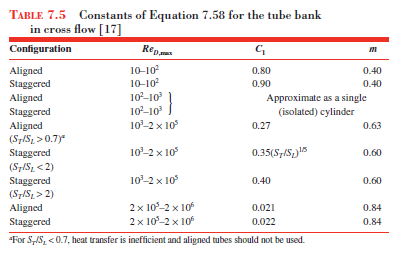

Table for C and M coeffiecents. 

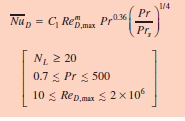

At least 20 tubes(**5 not 20 need correction factor**)

Prandlt number range, Reynolds number range

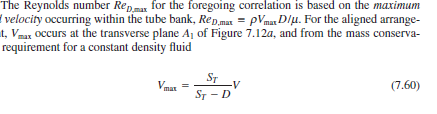

Input vector creation and graphing

AirSpeed = 0:0.1:10;
DynRatioL = 1.05;
DynAirSpeed = AirSpeed * DynRatioL;
%[y1,y2] = HeatLoss(AirSpeed,DynAirSpeed)
[HeatLoss, DynHeatLoss] = Heatloss(AirSpeed, DynAirSpeed);

DynDiameterCells = 0.0192

densityAir = 1.1274

thermMassAir = 1.0069e+03

DynSl = 0.0360

ReynoldsNumber = 1.0e+04 *

         0    0.0436    0.0872    0.1308    0.1744    0.2180    0.2616    0.3052    0.3488    0.3924    0.4360    0.4796    0.5232    0.5668    0.6104    0.6540    0.6976    0.7412    0.7848    0.8284    0.8720    0.9156    0.9592    1.0028    1.0464    1.0900    1.1336    1.1772    1.2208    1.2644    1.3080    1.3516    1.3952    1.4388    1.4824    1.5260    1.5696    1.6132    1.6568    1.7004    1.7440    1.7876    1.8312    1.8748    1.9184    1.9620    2.0056    2.0492    2.0928    2.1364


DynReynoldsNumber = 1.0e+04 *

         0    0.0481    0.0961    0.1442    0.1923    0.2403    0.2884    0.3365    0.3846    0.4326    0.4807    0.5288    0.5768    0.6249    0.6730    0.7210    0.7691    0.8172    0.8652    0.9133    0.9614    1.0095    1.0575    1.1056    1.1537    1.2017    1.2498    1.2979    1.3459    1.3940    1.4421    1.4901    1.5382    1.5863    1.6344    1.6824    1.7305    1.7786    1.8266    1.8747    1.9228    1.9708    2.0189    2.0670    2.1150    2.1631    2.2112    2.2593    2.3073    2.3554


To = 42.5798

To = 42.6015

qPrimeLadjust = 1.0e+03 *

         0    0.0661    0.1003    0.1279    0.1520    0.1737    0.1938    0.2126    0.2303    0.2472    0.2633    0.2788    0.2938    0.3082    0.3222    0.3359    0.3491    0.3620    0.3747    0.3870    0.3991    0.4110    0.4226    0.4340    0.4453    0.4563    0.4672    0.4779    0.4884    0.4988    0.5091    0.5192    0.5292    0.5390    0.5488    0.5584    0.5679    0.5773    0.5866    0.5958    0.6050    0.6140    0.6229    0.6318    0.6406    0.6493    0.6579    0.6664    0.6749    0.6833


DynqPrimeLadjust = 1.0e+03 *

         0    0.0736    0.1116    0.1424    0.1692    0.1934    0.2158    0.2367    0.2564    0.2752    0.2932    0.3104    0.3271    0.3432    0.3588    0.3739    0.3887    0.4031    0.4172    0.4309    0.4444    0.4576    0.4705    0.4833    0.4958    0.5080    0.5201    0.5321    0.5438    0.5554    0.5668    0.5780    0.5892    0.6001    0.6110    0.6217    0.6323    0.6428    0.6531    0.6634    0.6736    0.6836    0.6936    0.7034    0.7132    0.7229    0.7325    0.7420    0.7514    0.7608



hold on
ylabel('HeatLoss[w]');
plot(AirSpeed,HeatLoss,'.')
plot(DynAirSpeed/DynRatioL,DynHeatLoss/DynRatioL^2,'-')
%yyaxis right
%plot(z,AirSpeed,'.')
xlabel('AirSpeed at Entrance [m/s]');
%ylabel('Ploss');
var2 = battTemp-273.15;
var1 = tempHigh-273;
title_string = sprintf("AirSpeed Vs Heatloss at Ambient %.2f C and Battery Temp %.2f",var1,var2)

title_string = "AirSpeed Vs Heatloss at Ambient 42.15 C and Battery Temp 50.00"

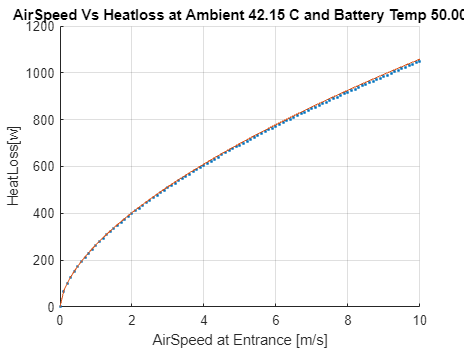

title(title_string)
grid on;
hold off

function [HeatLoss,DynHeatLoss] = Heatloss(AirSpeed,DynAirSpeed)


Basic

%Reynolds Number Calcs
    BattColumns = 5;
    BatteryRows =23;
    tempLow = 40+ 273.15;
    battTemp = 50+ 273.15;
    tempHigh = 42.57 + 273.15;
    DiameterCells = 18.3/1000; % CHANGE THIS BECAUSE NO GAP
  DynRatioL = 1.05;
    DynDiameterCells = DiameterCells * DynRatioL



    dynViscosity = py.CoolProp.CoolProp.PropsSI('V', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    densityAir = py.CoolProp.CoolProp.PropsSI('D', 'T', tempLow, 'P|not_imposed', 101325, 'air')
    thermCond = py.CoolProp.CoolProp.PropsSI('L', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    ConstPNum = py.CoolProp.CoolProp.PropsSI('C', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    thermMassAir = py.CoolProp.CoolProp.PropsSI('C', 'T', tempLow, 'P|not_imposed', 101325, 'air')
    KinViscosity = dynViscosity/densityAir;


% Vert vs Horiz Spacing
    St = 24.3/1000;% spacing between columns
    DynSt = St*DynRatioL;
    Sl = 34.3/1000;%center spacing in direction of initial airflow
    DynSl = Sl* DynRatioL
    Vmax =  St.*AirSpeed./(St-DiameterCells);
    DynVmax =  DynSt.*DynAirSpeed./(DynSt-DynDiameterCells);


    ReynoldsNumber =  Vmax * DiameterCells / KinViscosity 
    DynReynoldsNumber =  DynVmax * DynDiameterCells / KinViscosity 
    
    PrandtlAirLow = py.CoolProp.CoolProp.PropsSI('Prandtl', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    PrandtlAirHigh = py.CoolProp.CoolProp.PropsSI('Prandtl', 'T', tempHigh, 'P|not_imposed', 101325, 'air');

    C1 = 0.35*(St/Sl)^(1/5);
    DynC1 = 0.35*(DynSt/DynSl)^(1/5);
    mVal = 0.6; % Table
    C2 = 0.95; %Table (correction factor for 5)



    NusseltD = C2*C1*ReynoldsNumber.^mVal.*(PrandtlAirLow.^0.36).*(PrandtlAirLow./PrandtlAirHigh).^(0.25);
    DynNusseltD = C2*DynC1*DynReynoldsNumber.^mVal.*(PrandtlAirLow.^0.36).*(PrandtlAirLow./PrandtlAirHigh).^(0.25);
    
    Hline = NusseltD*thermCond/DiameterCells;
    DynHline = DynNusseltD*thermCond/DynDiameterCells;

Adjusted Delta for warming


    insideVarTop = (-pi*DiameterCells*(BattColumns*BatteryRows)*Hline);
    DyninsideVarTop = (-pi*DynDiameterCells*(BattColumns*BatteryRows)*DynHline);
    
    insideVarBot = (densityAir.*AirSpeed.*(BatteryRows)*St*ConstPNum);
    DyninsideVarBot = (densityAir.*DynAirSpeed.*(BatteryRows)*St*ConstPNum);
    
    adjDelTso = (battTemp - tempHigh)/(battTemp - tempLow) * exp(insideVarTop/insideVarBot);
    DynadjDelTso = (battTemp - tempHigh)/(battTemp - tempLow) * exp(DyninsideVarTop/DyninsideVarBot);
    To = -((battTemp - tempLow) * exp(insideVarTop/insideVarBot))+battTemp -273.15
    To = -((battTemp - tempLow) * exp(DyninsideVarTop/DyninsideVarBot))+battTemp -273.15

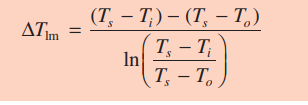

    deltTlm = (battTemp-tempLow)-(adjDelTso)/(log((battTemp-tempLow)/(adjDelTso)));
    DyndeltTlm = (battTemp-tempLow)-(DynadjDelTso)/(log((battTemp-tempLow)/(DynadjDelTso)));

    qPrime = (BatteryRows*BattColumns)*(Hline*pi*DiameterCells*deltTlm);%in KW per m
    DynqPrime = (BatteryRows*BattColumns)*(DynHline*pi*DynDiameterCells*DyndeltTlm);%in KW per m
    qPrimeLadjust = qPrime*0.065%Temp dissapated
    DynqPrimeLadjust = DynqPrime*DynRatioL*0.065%Temp dissapated
    areaPath = St*BattColumns*0.065;
    DynareaPath = DynSt*BattColumns*0.065*DynRatioL;

pressure loss

%PRESSURE LOSS DOES NOT HAVE DYN ADJUSTMENTS right now    
%PRESSURE LOSS DOES NOT HAVE DYN ADJUSTMENTS right now  
%PRESSURE LOSS DOES NOT HAVE DYN ADJUSTMENTS right now  
%PRESSURE LOSS DOES NOT HAVE DYN ADJUSTMENTS right now  
%PRESSURE LOSS DOES NOT HAVE DYN ADJUSTMENTS right now  

Pt = St/DiameterCells;
    Pl = Sl/DiameterCells;
    PTPL = (Pt-1)/(Pl-1);

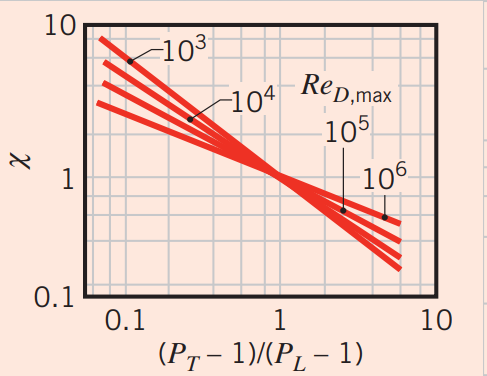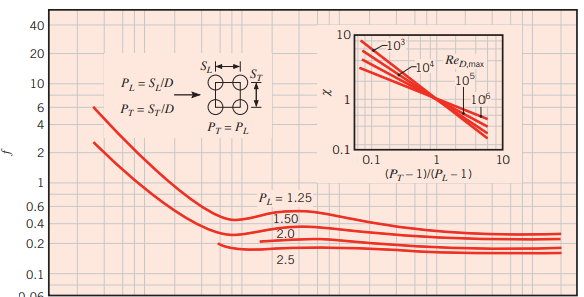

    fancyX = 1.4;
    fricFactor = 0.22;

    deltPLoss = 5.* fancyX .* (densityAir./2.*Vmax.^2) .* fricFactor;

    HeatLoss = qPrimeLadjust;
    DynHeatLoss = DynqPrimeLadjust;

end